clear all
clc
close all

**Polyhedron from inequalities**

To define a polyhedron with the form of:

x | F*x<= f

One can use the function Polyhedron(F, f)

F = randn(10,2);
f = ones(10,1);
P = Polyhedron(F,f)

MOSEK Version 10.1.12 (Build date: 2023-9-20 10:51:32)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86

Polyhedron in R^2 with representations:
    H-rep (redundant)   : Inequalities  10 | Equalities   0
    V-rep               : Unknown (call computeVRep() to compute)
Functions : none


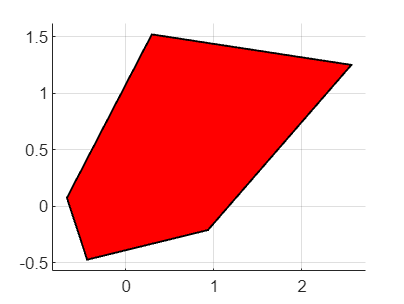

plot(P)

Obtaining inequalities:

F = P.A;
f = P.b;


Obtaining vertices:

V = P.V;

**Polyhedron from vertices**

v = randn(10,2);
P2 = Polyhedron(v)

Polyhedron in R^2 with representations:
    H-rep               : Unknown (call computeHRep() to compute)
    V-rep (redundant)   : Vertices  10 | Rays   0
Functions : none


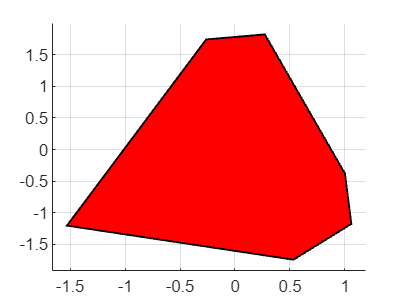

plot(P2)

**Intersection of polyhedra**

plot(P,P2)
hold on
I = intersect(P,P2);

Minimun representation of intersection:

I.minHRep

Polyhedron in R^2 with representations:
    H-rep (irredundant) : Inequalities   6 | Equalities   0
    V-rep               : Unknown (call computeVRep() to compute)
Functions : none


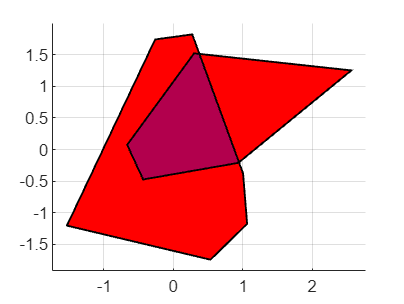

I.plot('alpha', .3, 'color', 'b')
hold off

**Polythopic projection**

P = Polyhedron(randn(30,3), ones(30,1))+ [0;0;1]

Polyhedron in R^3 with representations:
    H-rep (redundant)   : Inequalities  30 | Equalities   0
    V-rep               : Unknown (call computeVRep() to compute)
Functions : none


plot(P)
hold on
proj = P.projection(1:2)

Polyhedron in R^2 with representations:
    H-rep               : Unknown (call computeHRep() to compute)
    V-rep (redundant)   : Vertices  26 | Rays   0
Functions : none


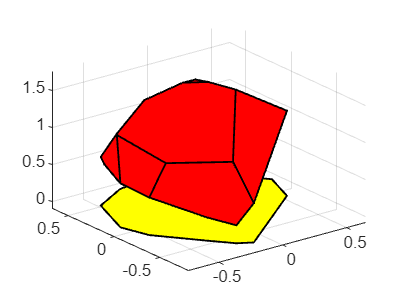

plot(proj, 'color', 'y')
hold off

**Subset test:**

P = Polyhedron(randn(10,2), ones(10,1))

Polyhedron in R^2 with representations:
    H-rep (redundant)   : Inequalities  10 | Equalities   0
    V-rep               : Unknown (call computeVRep() to compute)
Functions : none


Q = Polyhedron(randn(10,2), ones(10,1))

Polyhedron in R^2 with representations:
    H-rep (redundant)   : Inequalities  10 | Equalities   0
    V-rep               : Unknown (call computeVRep() to compute)
Functions : none


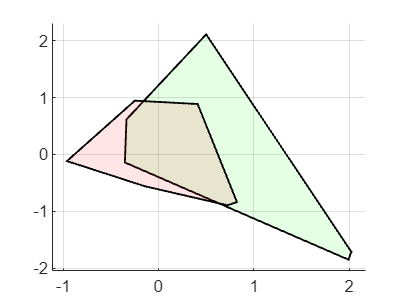


plot(P, 'alpha', 0.1, 'color', 'g', Q, 'alpha', 0.1, 'color','r')

In order to define weather a polyhedron P is inside anothor Q or not, one has to maximize in each direction of Q and find maximal postion of vertex. 

The position of vertex of Q are normalized to 1, wereas the potion of vertex of P indicate how relative the vertex is to the direction of Q. 

If position of vertex P>1--> that vertex is not contained in Q

If position of vertex P<1--> that vertex is contained in Q

To obtain position of maximized vertex:

[P.support(Q.A') Q.b]

ans =     2.2875    1.0000
    2.3348    1.0000
    1.2126    1.0000
    1.7581    1.0000
    2.5912    1.0000
    1.0385    1.0000


Otherwise:

if P <= Q, fprintf('P is a subset of Q\n');
elseif Q <= P, fprintf('Q is a subset of P\n');
end
if P == Q, fprintf('P is equal to Q\n'); end